# Chapter 5 - Frequency Response Analysis

## Section 5 : Frequency - Response Approach to Control System Compensation

This section reviews Lead compensation, Lag compensation, and Lag-Lead compensation of control systems via Bode diagram approach. 

clear all
clc

- LEAD COMPENSATION NOTES

- Assume that the Lead Compensator :  $G_c \left(s\right)=K_c \alpha \left(\frac{Ts+1}{\alpha Ts+1}\right)$ , where 0 < $\alpha$ < 1    

- Lead Angle : $\phi ={tan}^{−1} \left(\omega T\right)−{tan}^{−1} \left(\alpha \omega T\right)$

- Frequency that produces the maximum Lead Angle : $\omega_{m\text{ }} =\text{ }\frac{1}{\left(\sqrt{\alpha T}\right)}$

- Maximum Lead Angle : $sin\left(\phi_m \right)=\text{ }\frac{1−\text{ }\alpha }{1+\text{ }\alpha }$

- Using these equations and a desired gain crossover / phase crossover frequencies, determine the value for $\alpha$ and plug into $G_{c\text{ }}$

## 5-22 Determine the gain, K, of the control system such that PM = 60 deg

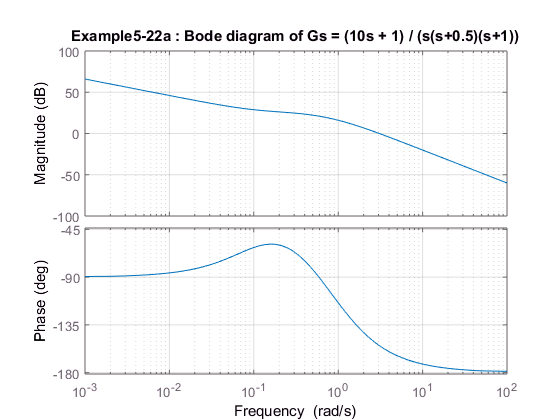

% Open Loop TF
num = [10 1];
den = [1 1.5 0.5 0];


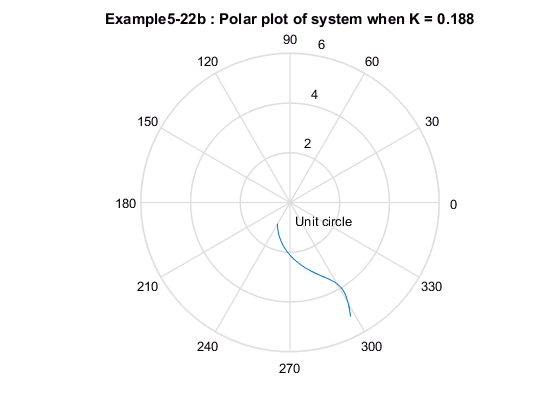

% Plot the bode diagram of Open Loop TF when K = 1
figure
bode( num, den), grid
title('Example5-22a : Bode diagram of Gs = (10s + 1) / (s(s+0.5)(s+1))')
    % The PM = 60 deg when the frequency is 1.15 rad/ sec
    % The magnitude at w = 1.15 rad/sec is equal to -14.5 dB
    % 20 * log(K) = -14.5 dB
K = 0.188 

% Verify results using Nyquist Diagram 
num2 = [1.88 0.188];
den2 = [1 1.5 0.5 0];
w = 0.1: 0.01: 1.15;
[re, im, w] = nyquist(num2, den2, w);

%Define a complex vector, z, to draw Nyquist on polar plot
z = re + i*im;
r = abs(z);
th = angle(z);


% Draw polar plot
polar(th, r), grid
title( 'Example5-22b : Polar plot of system when K = 0.188')
text(0.2, -0.7, 'Unit circle')


## 5-23 Design a Lead Compensator, Gc, such that the PM = 50 deg and GM > 10 dB

clear all
clc

% Open Loop TF of the closed loop sys without compensation


Gs =
 
       0.2
  -------------
  0.2 s^3 + s^2
 
Continuous-time transfer function.



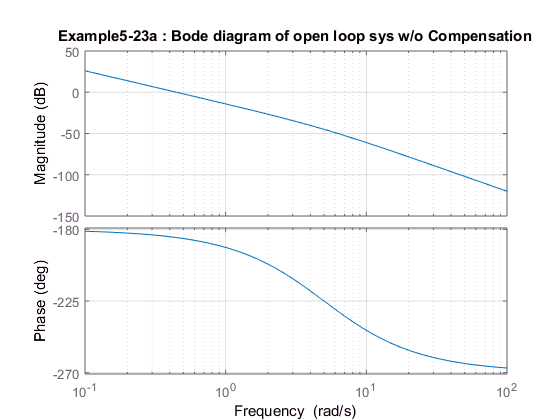

num = [1] * 0.2;
den = [1 5 0 0] * 0.2;

Gs = tf(num, den) 


figure
bode(num, den), grid
title('Example5-23a : Bode diagram of open loop sys w/o Compensation')
    % Based on results of Bode diagram: 
        % Set the gain crossover frequency to be w = 1 rad/sec
        % At w = 1 rad/sec, the PM = 11.31 deg. Want a PM = 50 deg
        % So, Max lead angle = 50 + 11.31 = 61.31 deg of compensation at w = 1 rad/sec

        
% Determine alpha based on the angle compensation amount
phi_max = 61.31 * pi / 180; 
alpha = (sin(phi_max) - 1) / (-1 - sin(phi_max));

% Determine T from w_m = 1/(sqrt(alpha(T))), assuming w_m = 1
T = 1 / sqrt(alpha);

% Determine the compensator, Gc 


Gc =
 
   3.91 s + 1
  ------------
  0.2557 s + 1
 
Continuous-time transfer function.



num2 = [T 1];
den2 = [alpha*T 1];


Closed_loop_sys =
 
          0.7821 s + 0.2
  ------------------------------
  0.05115 s^4 + 0.4557 s^3 + s^2
 
Continuous-time transfer function.



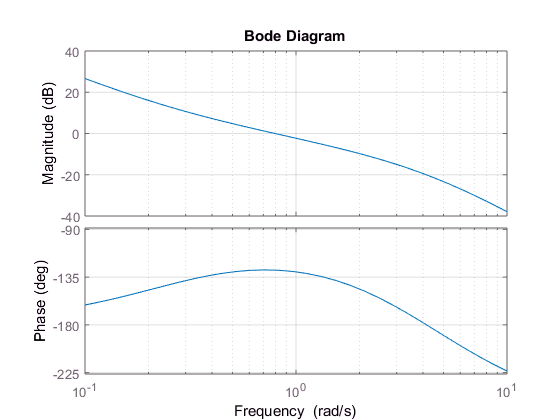


Gc = tf(num2, den2)
% The closed loop transfer function of Gc and Gs 

Closed_loop_sys = Gc * Gs

bode(Closed_loop_sys), grid
xlim([10^-1, 10^1]);

% Determine the magnitude a specific frequencies
ww = [0.5 1 2];
[mag, ph, ww] = bode(Closed_loop_sys, ww);
magdB(1) = 20 * log10(mag(:,:,1));

ans =     0.5000    4.7810
    1.0000   -2.3055
    2.0000   -9.7391


magdB(2) = 20 * log10(mag(:,:,2));
magdB(3) = 20 * log10(mag(:,:,3));

[ww magdB']
% At w = 1, the magnitude is equal to -2.3055
% Therefore, the magnitude curve must be raised by 2.3055 dB
% so that the magnitude curve crosses 0 dB at w = 1 rad/sec


Kc = 19.9400

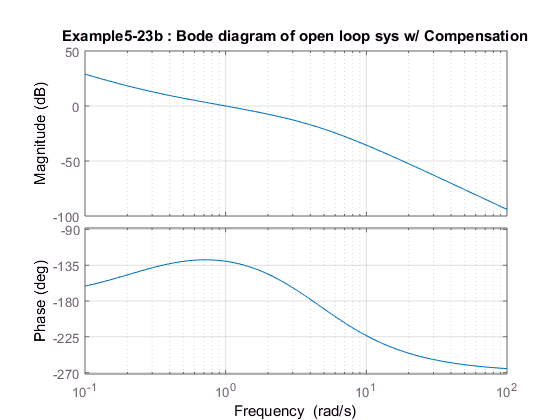

% Therefore, the magnitude not in dB =>  20 log10(0.06541* Kc) = 2.3055
% Solve for Kc

Kc = 19.94

% Next, plot bode plot with Kc = 19.94
num3 = [ 1.01994 0.26086];
den3 = [0.05116 0.4558 1 0 0 ];
w = logspace(-1, 2, 100);


figure
bode(num3, den3, w), grid;
title('Example5-23b : Bode diagram of open loop sys w/ Compensation')

ans =    17.7408   49.9939    4.1535    1.0001


%Deterimine gain margin, phase margin
[Gm, Pm, wcp, wcg] = margin(num3, den3);

 Gain margin = 17.74 dB


GmdB = 20*log10(Gm);

 Phase margin = 49.99 deg


[GmdB Pm wcp wcg]

disp(' Gain margin = 17.74 dB')
disp(' Phase margin = 49.99 deg')


sys1 =
 
         1.02 s + 0.2609
  ------------------------------
  0.05116 s^4 + 0.4558 s^3 + s^2
 
Continuous-time transfer function.



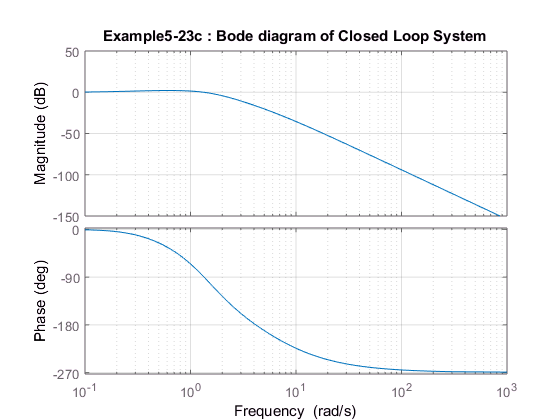



% Closed loop system 
sys1 = tf(num3, den3)
sys = feedback(sys1, [1]);


figure
bode(sys), grid
title('Example5-23c : Bode diagram of Closed Loop System')



## 5-24 Design a compensator such that the system has the following requirements:

% 1. Static velocity error constant = 20 1/sec
% 2. PM = 50 deg
% 3. GM >= 10 dB. 
























